clear all;

%FG1 = load('FixedGainSimu1.mat');
FG2 = load('FixedGainSimu2.mat');
%FG3 = load('FixedGainSimu3.mat');
GS = load('GainScheduledSimu.mat');
%GS0 = load('GainScheduledSimu0.mat');

t_list = FG2.Time(7501:end);

FG2_wind = FG2.Wind1VelX(7501:end);
GS_wind = GS.Wind1VelX(7501:end);

FG2_rotspeed = FG2.RotSpeed(7501:end);
GS_rotspeed = GS.RotSpeed(7501:end);

FG2_pangle = FG2.BlPitch1(7501:end);
GS_pangle = GS.BlPitch1(7501:end);

FG2_torq = FG2.GenTq(7501:end);
GS_torq = GS.GenTq(7501:end);

FG2_genP = FG2.GenPwr(7501:end);
GS_genP = GS.GenPwr(7501:end);

FG2_fo = FG2.NcIMUTAxs(7501:end);
GS_fo = GS.NcIMUTAxs(7501:end);

FG2_ss = FG2.NcIMUTAzs(7501:end);
GS_ss = GS.NcIMUTAzs(7501:end);



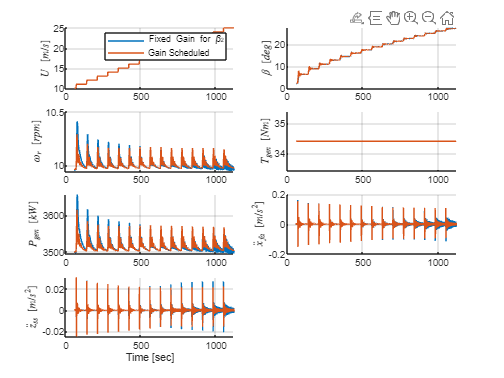

f = figure;
subplot(4,2,1);
hold on
plot(t_list, FG2_wind)
plot(t_list, GS_wind)
legend('Fixed Gain for \beta_2','Gain Scheduled')
ylabel('$$U \ [m/s]$$', 'Interpreter','latex')
grid on
hold off

subplot(4,2,2);
hold on
plot(t_list, FG2_pangle)
plot(t_list, GS_pangle)
ylabel('$$\beta \ [deg]$$', 'Interpreter','latex')
grid on
hold off

subplot(4,2,3);
hold on
plot(t_list, FG2_rotspeed)
plot(t_list, GS_rotspeed)
ylabel('$$\omega_r \ [rpm]$$', 'Interpreter','latex')
grid on
hold off

subplot(4,2,4);
hold on
plot(t_list, FG2_torq)
plot(t_list, GS_torq)
ylabel('$$T_{gen} \ [Nm]$$', 'Interpreter','latex')
grid on
hold off

subplot(4,2,5);
hold on
plot(t_list, FG2_genP)
plot(t_list, GS_genP)
ylabel('$$P_{gen} \ [kW]$$', 'Interpreter','latex')
grid on
hold off

subplot(4,2,6);
hold on
plot(t_list, FG2_fo)
plot(t_list, GS_fo)
ylabel('$$\ddot{x}_{fa} \ [m/s^2]$$', 'Interpreter','latex')
grid on
hold off

subplot(4,2,7);
hold on
plot(t_list, FG2_ss)
plot(t_list, GS_ss)
xlabel('Time [sec]')
ylabel('$$\ddot{z}_{ss} \ [m/s^2]$$', 'Interpreter','latex')
grid on
hold off


saveas(f, 'FG_vs_GS.png')